# **ColorThreshold Test**

## **Choose Image**

I = "image3.jpg"

I = "image3.jpg"

## **Functions**

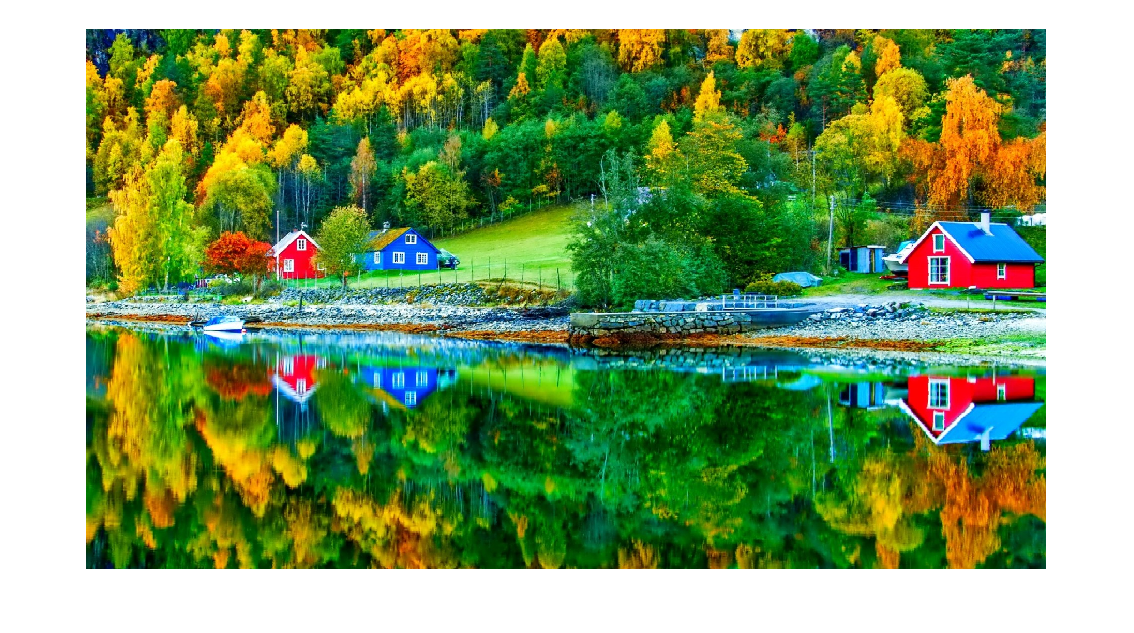

imshow(I)

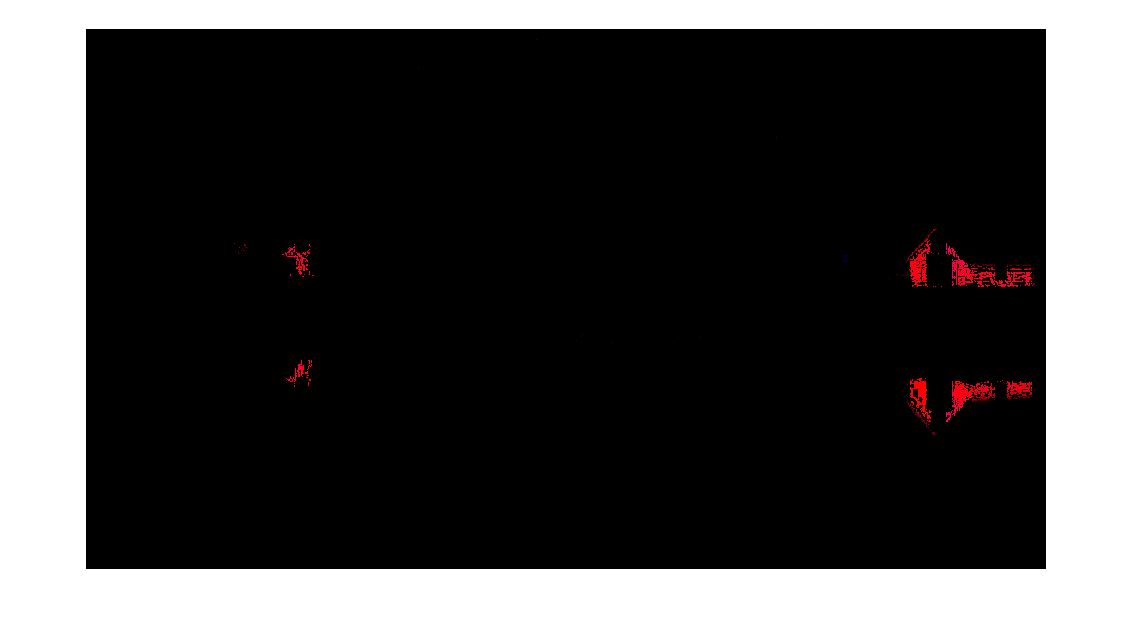


RGB = imread(I);
[~, maskedRGBImage] = createMaskGreen(RGB);

imshow(maskedRGBImage)

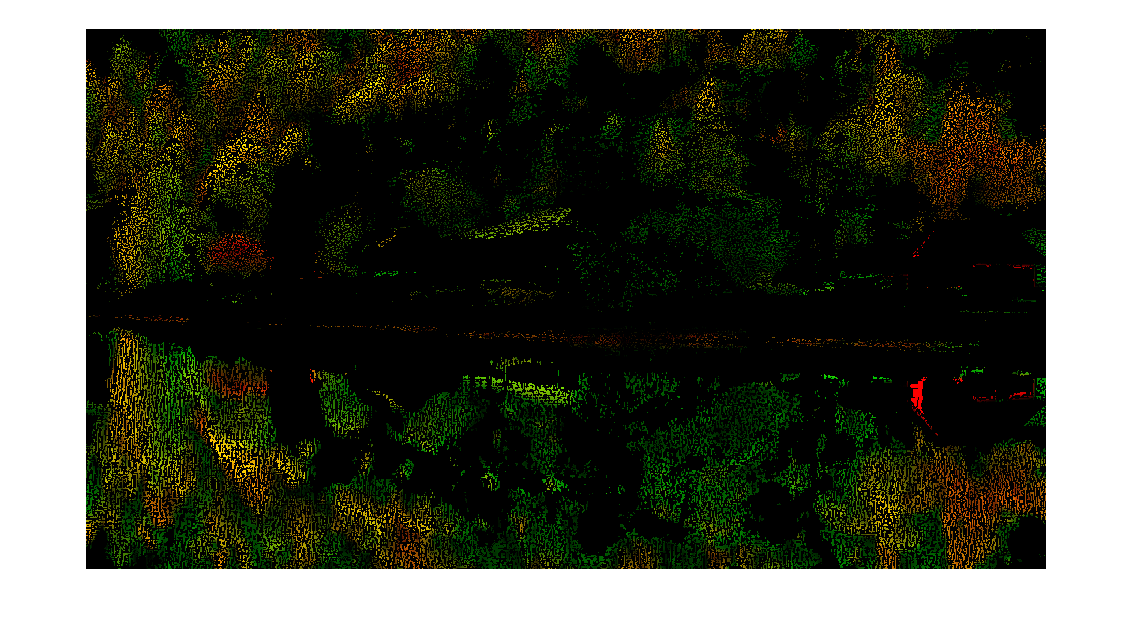


[~, maskedRGBImage] = createMaskBlue(RGB);

imshow(maskedRGBImage)

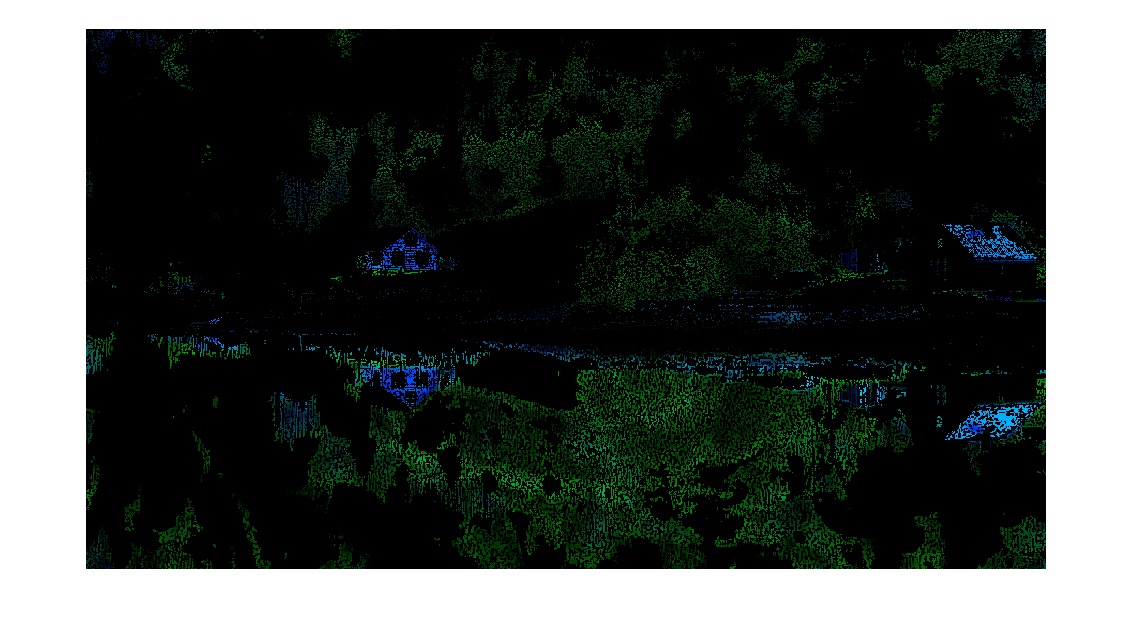



[BW, maskedRGBImage] = createMaskRed(RGB);

imshow(maskedRGBImage)

## **Green Function**

function [BW,maskedRGBImage] = createMaskGreen(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 27-Feb-2021
%------------------------------------------------------


% Convert RGB image to chosen color space
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 255.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 0.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 255.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end


## **Blue Function**

function [BW,maskedRGBImage] = createMaskBlue(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 27-Feb-2021
%------------------------------------------------------


% Convert RGB image to chosen color space
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 255.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 255.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 0.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end


## **Red Function**


function [BW,maskedRGBImage] = createMaskRed(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 27-Feb-2021
%------------------------------------------------------


% Convert RGB image to chosen color space
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 0.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 255.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 255.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end